clear all, close all, clc

### **Q1_1**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q01_1', 'Al_S3_Q01_1')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q01_1;
B_Q11 = Al_S3_Q01_1;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q01_1_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q01_1_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q01_1_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q01_1_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q01_1_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q01_1_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q01_1_Rlg;                             % Raleigh
Al_S1_Q01_1_SLC;                             % SLC
Al_S1_Q01_1_Chg;                             % Chicago

Al_S3_Q01_1_Rlg;                             % Raleigh
Al_S3_Q01_1_SLC;                             % SLC
Al_S3_Q01_1_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q01_1_Rlg, Al_S3_Q01_1_Rlg)

la1 = 1.1300

la2 = 1.0400

sh_f = 0.9204

P = rank_sum(Al_S1_Q01_1_Rlg, Al_S3_Q01_1_Rlg)

P = 0.0047


[y1, y2] = likert4(Al_S1_Q01_1_Rlg, Al_S3_Q01_1_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q01_1_SLC, Al_S3_Q01_1_SLC)

la1 = 3.5900

la2 = 3.6000

sh_f = 1.0028

P = rank_sum(Al_S1_Q01_1_SLC, Al_S3_Q01_1_SLC)

P = 0.3995


[y1, y2] = likert4(Al_S1_Q01_1_SLC, Al_S3_Q01_1_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q01_1_Chg, Al_S3_Q01_1_Chg)

la1 = 3.4700

la2 = 3.6300

sh_f = 1.0461

P = rank_sum(Al_S1_Q01_1_Chg, Al_S3_Q01_1_Chg)

P = 0.6300


[y1, y2] = likert4(Al_S1_Q01_1_Chg, Al_S3_Q01_1_Chg);


### **Q1_2**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q01_2', 'Al_S3_Q01_2')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q01_2;
B_Q11 = Al_S3_Q01_2;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q01_2_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q01_2_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q01_2_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q01_2_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q01_2_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q01_2_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q01_2_Rlg;                             % Raleigh
Al_S1_Q01_2_SLC;                             % SLC
Al_S1_Q01_2_Chg;                             % Chicago

Al_S3_Q01_2_Rlg;                             % Raleigh
Al_S3_Q01_2_SLC;                             % SLC
Al_S3_Q01_2_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q01_2_Rlg, Al_S3_Q01_2_Rlg)

la1 = 1.0400

la2 = 1.0800

sh_f = 1.0385

P = rank_sum(Al_S1_Q01_2_Rlg, Al_S3_Q01_2_Rlg)

P = 5.9685e-04


[y1, y2] = likert4(Al_S1_Q01_2_Rlg, Al_S3_Q01_2_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q01_2_SLC, Al_S3_Q01_2_SLC)

la1 = 3.7400

la2 = 3.7600

sh_f = 1.0053

P = rank_sum(Al_S1_Q01_2_SLC, Al_S3_Q01_2_SLC)

P = 0.5038


[y1, y2] = likert4(Al_S1_Q01_2_SLC, Al_S3_Q01_2_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q01_2_Chg, Al_S3_Q01_2_Chg)

la1 = 3.5300

la2 = 3.4700

sh_f = 0.9830

P = rank_sum(Al_S1_Q01_2_Chg, Al_S3_Q01_2_Chg)

P = 0.6827


[y1, y2] = likert4(Al_S1_Q01_2_Chg, Al_S3_Q01_2_Chg);

### **Q1_3**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q01_3', 'Al_S3_Q01_3')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q01_3;
B_Q11 = Al_S3_Q01_3;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q01_3_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q01_3_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q01_3_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q01_3_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q01_3_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q01_3_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q01_3_Rlg;                             % Raleigh
Al_S1_Q01_3_SLC;                             % SLC
Al_S1_Q01_3_Chg;                             % Chicago

Al_S3_Q01_3_Rlg;                             % Raleigh
Al_S3_Q01_3_SLC;                             % SLC
Al_S3_Q01_3_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q01_3_Rlg, Al_S3_Q01_3_Rlg)

la1 = 1.5400

la2 = 1.4400

sh_f = 0.9351

P = rank_sum(Al_S1_Q01_3_Rlg, Al_S3_Q01_3_Rlg)

P = 0.0061


[y1, y2] = likert4(Al_S1_Q01_3_Rlg, Al_S3_Q01_3_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q01_3_SLC, Al_S3_Q01_3_SLC)

la1 = 2.8100

la2 = 2.8400

sh_f = 1.0107

P = rank_sum(Al_S1_Q01_3_SLC, Al_S3_Q01_3_SLC)

P = 0.3843


[y1, y2] = likert4(Al_S1_Q01_3_SLC, Al_S3_Q01_3_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q01_3_Chg, Al_S3_Q01_3_Chg)

la1 = 2.9500

la2 = 2.8900

sh_f = 0.9797

P = rank_sum(Al_S1_Q01_3_Chg, Al_S3_Q01_3_Chg)

P = 0.8381


[y1, y2] = likert4(Al_S1_Q01_3_Chg, Al_S3_Q01_3_Chg);

### **Q1_4**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q01_4', 'Al_S3_Q01_4')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q01_4;
B_Q11 = Al_S3_Q01_4;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q01_4_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q01_4_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q01_4_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q01_4_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q01_4_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q01_4_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q01_4_Rlg;                             % Raleigh
Al_S1_Q01_4_SLC;                             % SLC
Al_S1_Q01_4_Chg;                             % Chicago

Al_S3_Q01_4_Rlg;                             % Raleigh
Al_S3_Q01_4_SLC;                             % SLC
Al_S3_Q01_4_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q01_4_Rlg, Al_S3_Q01_4_Rlg)

la1 = 1.5400

la2 = 1.5200

sh_f = 0.9870

P = rank_sum(Al_S1_Q01_4_Rlg, Al_S3_Q01_4_Rlg)

P = 0.0017


[y1, y2] = likert4(Al_S1_Q01_4_Rlg, Al_S3_Q01_4_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q01_4_SLC, Al_S3_Q01_4_SLC)

la1 = 2.9600

la2 = 2.7600

sh_f = 0.9324

P = rank_sum(Al_S1_Q01_4_SLC, Al_S3_Q01_4_SLC)

P = 0.0670


[y1, y2] = likert4(Al_S1_Q01_4_SLC, Al_S3_Q01_4_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q01_4_Chg, Al_S3_Q01_4_Chg)

la1 = 3.1600

la2 = 3.2100

sh_f = 1.0158

P = rank_sum(Al_S1_Q01_4_Chg, Al_S3_Q01_4_Chg)

P = 0.8267


[y1, y2] = likert4(Al_S1_Q01_4_Chg, Al_S3_Q01_4_Chg);

### **Q1_5**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q01_5', 'Al_S3_Q01_5')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q01_5;
B_Q11 = Al_S3_Q01_5;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q01_5_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q01_5_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q01_5_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q01_5_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q01_5_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q01_5_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q01_5_Rlg;                             % Raleigh
Al_S1_Q01_5_SLC;                             % SLC
Al_S1_Q01_5_Chg;                             % Chicago

Al_S3_Q01_5_Rlg;                             % Raleigh
Al_S3_Q01_5_SLC;                             % SLC
Al_S3_Q01_5_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q01_5_Rlg, Al_S3_Q01_5_Rlg)

la1 = 1.2100

la2 = 1.2400

sh_f = 1.0248

P = rank_sum(Al_S1_Q01_5_Rlg, Al_S3_Q01_5_Rlg)

P = 6.7320e-04


[y1, y2] = likert4(Al_S1_Q01_5_Rlg, Al_S3_Q01_5_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q01_5_SLC, Al_S3_Q01_5_SLC)

la1 = 3.3000

la2 = 3.5600

sh_f = 1.0788

P = rank_sum(Al_S1_Q01_5_SLC, Al_S3_Q01_5_SLC)

P = 0.7695


[y1, y2] = likert4(Al_S1_Q01_5_SLC, Al_S3_Q01_5_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q01_5_Chg, Al_S3_Q01_5_Chg)

la1 = 3.3700

la2 = 3.1600

sh_f = 0.9377

P = rank_sum(Al_S1_Q01_5_Chg, Al_S3_Q01_5_Chg)

P = 0.4927


[y1, y2] = likert4(Al_S1_Q01_5_Chg, Al_S3_Q01_5_Chg);

### **Q1_C**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q01_C', 'Al_S3_Q01_C')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q01_C;
B_Q11 = Al_S3_Q01_C;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q01_C_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q01_C_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q01_C_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q01_C_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q01_C_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q01_C_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q01_C_Rlg;                             % Raleigh
Al_S1_Q01_C_SLC;                             % SLC
Al_S1_Q01_C_Chg;                             % Chicago

Al_S3_Q01_C_Rlg;                             % Raleigh
Al_S3_Q01_C_SLC;                             % SLC
Al_S3_Q01_C_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q01_C_Rlg, Al_S3_Q01_C_Rlg)

la1 = 1.1700

la2 = 1.2400

sh_f = 1.0598

P = rank_sum(Al_S1_Q01_C_Rlg, Al_S3_Q01_C_Rlg)

P = 3.1203e-04


[y1, y2] = likert4(Al_S1_Q01_C_Rlg, Al_S3_Q01_C_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q01_C_SLC, Al_S3_Q01_C_SLC)

la1 = 3.3700

la2 = 3.2800

sh_f = 0.9733

P = rank_sum(Al_S1_Q01_C_SLC, Al_S3_Q01_C_SLC)

P = 0.1331


[y1, y2] = likert4(Al_S1_Q01_C_SLC, Al_S3_Q01_C_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q01_C_Chg, Al_S3_Q01_C_Chg)

la1 = 3.3700

la2 = 3.3200

sh_f = 0.9852

P = rank_sum(Al_S1_Q01_C_Chg, Al_S3_Q01_C_Chg)

P = 0.7815


[y1, y2] = likert4(Al_S1_Q01_C_Chg, Al_S3_Q01_C_Chg);

### **Q2**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q02', 'Al_S3_Q02')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q02;
B_Q11 = Al_S3_Q02;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q02_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q02_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q02_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q02_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q02_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q02_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q02_Rlg;                             % Raleigh
Al_S1_Q02_SLC;                             % SLC
Al_S1_Q02_Chg;                             % Chicago

Al_S3_Q02_Rlg;                             % Raleigh
Al_S3_Q02_SLC;                             % SLC
Al_S3_Q02_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q02_Rlg, Al_S3_Q02_Rlg)

la1 = 1.4300

la2 = 1.2100

sh_f = 0.8462

P = rank_sum(Al_S1_Q02_Rlg, Al_S3_Q02_Rlg)

P = 0.3503


[y1, y2] = likert5(Al_S1_Q02_Rlg, Al_S3_Q02_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q02_SLC, Al_S3_Q02_SLC)

la1 = 4.2600

la2 = 4.6700

sh_f = 1.0962

P = rank_sum(Al_S1_Q02_SLC, Al_S3_Q02_SLC)

P = 0.5097


[y1, y2] = likert5(Al_S1_Q02_SLC, Al_S3_Q02_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q02_Chg, Al_S3_Q02_Chg)

la1 = 4.2100

la2 = 4.3700

sh_f = 1.0380

P = rank_sum(Al_S1_Q02_Chg, Al_S3_Q02_Chg)

P = 0.9302


[y1, y2] = likert5(Al_S1_Q02_Chg, Al_S3_Q02_Chg);

### **Q3_1**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q03_1', 'Al_S3_Q03_1')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q03_1;
B_Q11 = Al_S3_Q03_1;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q03_1_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q03_1_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q03_1_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q03_1_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q03_1_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q03_1_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q03_1_Rlg;                             % Raleigh
Al_S1_Q03_1_SLC;                             % SLC
Al_S1_Q03_1_Chg;                             % Chicago

Al_S3_Q03_1_Rlg;                             % Raleigh
Al_S3_Q03_1_SLC;                             % SLC
Al_S3_Q03_1_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q03_1_Rlg, Al_S3_Q03_1_Rlg)

la1 = 1.5400

la2 = 1.7600

sh_f = 1.1429

P = rank_sum(Al_S1_Q03_1_Rlg, Al_S3_Q03_1_Rlg)

P = 7.3207e-05


[y1, y2] = likert4(Al_S1_Q03_1_Rlg, Al_S3_Q03_1_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q03_1_SLC, Al_S3_Q03_1_SLC)

la1 = 2.9200

la2 = 2.7900

sh_f = 0.9555

P = rank_sum(Al_S1_Q03_1_SLC, Al_S3_Q03_1_SLC)

P = 0.6536

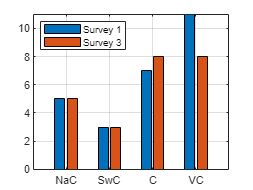


[y1, y2] = likert4(Al_S1_Q03_1_SLC, Al_S3_Q03_1_SLC);



%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q03_1_Chg, Al_S3_Q03_1_Chg)

la1 = 1.9500

la2 = 2.0500

sh_f = 1.0513

P = rank_sum(Al_S1_Q03_1_Chg, Al_S3_Q03_1_Chg)

P = 0.8609


[y1, y2] = likert4(Al_S1_Q03_1_Chg, Al_S3_Q03_1_Chg);

### **Q3_2**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q03_2', 'Al_S3_Q03_2')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q03_2;
B_Q11 = Al_S3_Q03_2;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q03_2_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q03_2_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q03_2_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q03_2_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q03_2_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q03_2_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q03_2_Rlg;                             % Raleigh
Al_S1_Q03_2_SLC;                             % SLC
Al_S1_Q03_2_Chg;                             % Chicago

Al_S3_Q03_2_Rlg;                             % Raleigh
Al_S3_Q03_2_SLC;                             % SLC
Al_S3_Q03_2_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q03_2_Rlg, Al_S3_Q03_2_Rlg)

la1 = 1.5400

la2 = 1.7600

sh_f = 1.1429

P = rank_sum(Al_S1_Q03_2_Rlg, Al_S3_Q03_2_Rlg)

P = 7.3207e-05


[y1, y2] = likert4(Al_S1_Q03_2_Rlg, Al_S3_Q03_2_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q03_2_SLC, Al_S3_Q03_2_SLC)

la1 = 2.6700

la2 = 2.4200

sh_f = 0.9064

P = rank_sum(Al_S1_Q03_2_SLC, Al_S3_Q03_2_SLC)

P = 0.1379


[y1, y2] = likert4(Al_S1_Q03_2_SLC, Al_S3_Q03_2_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q03_2_Chg, Al_S3_Q03_2_Chg)

la1 = 2.0500

la2 = 1.8400

sh_f = 0.8976

P = rank_sum(Al_S1_Q03_2_Chg, Al_S3_Q03_2_Chg)

P = 0.5207


[y1, y2] = likert4(Al_S1_Q03_2_Chg, Al_S3_Q03_2_Chg);

### **Q3_3**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q03_3', 'Al_S3_Q03_3')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q03_3;
B_Q11 = Al_S3_Q03_3;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q03_3_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q03_3_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q03_3_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q03_3_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q03_3_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q03_3_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q03_3_Rlg;                             % Raleigh
Al_S1_Q03_3_SLC;                             % SLC
Al_S1_Q03_3_Chg;                             % Chicago

Al_S3_Q03_3_Rlg;                             % Raleigh
Al_S3_Q03_3_SLC;                             % SLC
Al_S3_Q03_3_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q03_3_Rlg, Al_S3_Q03_3_Rlg)

la1 = 1.4200

la2 = 1.5600

sh_f = 1.0986

P = rank_sum(Al_S1_Q03_3_Rlg, Al_S3_Q03_3_Rlg)

P = 1.2581e-04


[y1, y2] = likert4(Al_S1_Q03_3_Rlg, Al_S3_Q03_3_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q03_3_SLC, Al_S3_Q03_3_SLC)

la1 = 2.8500

la2 = 2.7100

sh_f = 0.9509

P = rank_sum(Al_S1_Q03_3_SLC, Al_S3_Q03_3_SLC)

P = 0.2881


[y1, y2] = likert4(Al_S1_Q03_3_SLC, Al_S3_Q03_3_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q03_3_Chg, Al_S3_Q03_3_Chg)

la1 = 2.1600

la2 = 2.2100

sh_f = 1.0231

P = rank_sum(Al_S1_Q03_3_Chg, Al_S3_Q03_3_Chg)

P = 0.8381


[y1, y2] = likert4(Al_S1_Q03_3_Chg, Al_S3_Q03_3_Chg);

### **Q3_4**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q03_4', 'Al_S3_Q03_4')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q03_4;
B_Q11 = Al_S3_Q03_4;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q03_4_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q03_4_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q03_4_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q03_4_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q03_4_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q03_4_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q03_4_Rlg;                             % Raleigh
Al_S1_Q03_4_SLC;                             % SLC
Al_S1_Q03_4_Chg;                             % Chicago

Al_S3_Q03_4_Rlg;                             % Raleigh
Al_S3_Q03_4_SLC;                             % SLC
Al_S3_Q03_4_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q03_4_Rlg, Al_S3_Q03_4_Rlg)

la1 = 1.7500

la2 = 1.6400

sh_f = 0.9371

P = rank_sum(Al_S1_Q03_4_Rlg, Al_S3_Q03_4_Rlg)

P = 0.0092


[y1, y2] = likert4(Al_S1_Q03_4_Rlg, Al_S3_Q03_4_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q03_4_SLC, Al_S3_Q03_4_SLC)

la1 = 2.5200

la2 = 2.3900

sh_f = 0.9484

P = rank_sum(Al_S1_Q03_4_SLC, Al_S3_Q03_4_SLC)

P = 0.3744


[y1, y2] = likert4(Al_S1_Q03_4_SLC, Al_S3_Q03_4_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q03_4_Chg, Al_S3_Q03_4_Chg)

la1 = 2.4200

la2 = 2.7900

sh_f = 1.1529

P = rank_sum(Al_S1_Q03_4_Chg, Al_S3_Q03_4_Chg)

P = 0.2429


[y1, y2] = likert4(Al_S1_Q03_4_Chg, Al_S3_Q03_4_Chg);

### **Q3_5**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q03_5', 'Al_S3_Q03_5')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q03_5;
B_Q11 = Al_S3_Q03_5;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q03_5_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q03_5_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q03_5_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q03_5_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q03_5_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q03_5_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q03_5_Rlg;                             % Raleigh
Al_S1_Q03_5_SLC;                             % SLC
Al_S1_Q03_5_Chg;                             % Chicago

Al_S3_Q03_5_Rlg;                             % Raleigh
Al_S3_Q03_5_SLC;                             % SLC
Al_S3_Q03_5_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q03_5_Rlg, Al_S3_Q03_5_Rlg)

la1 = 1.4200

la2 = 1.6800

sh_f = 1.1831

P = rank_sum(Al_S1_Q03_5_Rlg, Al_S3_Q03_5_Rlg)

P = 1.2127e-05


[y1, y2] = likert4(Al_S1_Q03_5_Rlg, Al_S3_Q03_5_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q03_5_SLC, Al_S3_Q03_5_SLC)

la1 = 2.5800

la2 = 2.5700

sh_f = 0.9961

P = rank_sum(Al_S1_Q03_5_SLC, Al_S3_Q03_5_SLC)

P = 0.8189


[y1, y2] = likert4(Al_S1_Q03_5_SLC, Al_S3_Q03_5_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q03_5_Chg, Al_S3_Q03_5_Chg)

la1 = 2.6300

la2 = 2.6300

sh_f = 1

P = rank_sum(Al_S1_Q03_5_Chg, Al_S3_Q03_5_Chg)

P = 0.9534


[y1, y2] = likert4(Al_S1_Q03_5_Chg, Al_S3_Q03_5_Chg);

### **Q3_C**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q03_C', 'Al_S3_Q03_C')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q03_C;
B_Q11 = Al_S3_Q03_C;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q03_C_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q03_C_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q03_C_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q03_C_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q03_C_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q03_C_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q03_C_Rlg;                             % Raleigh
Al_S1_Q03_C_SLC;                             % SLC
Al_S1_Q03_C_Chg;                             % Chicago

Al_S3_Q03_C_Rlg;                             % Raleigh
Al_S3_Q03_C_SLC;                             % SLC
Al_S3_Q03_C_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q03_C_Rlg, Al_S3_Q03_C_Rlg)

la1 = 1.5000

la2 = 1.6400

sh_f = 1.0933

P = rank_sum(Al_S1_Q03_C_Rlg, Al_S3_Q03_C_Rlg)

P = 8.3948e-05


[y1, y2] = likert4(Al_S1_Q03_C_Rlg, Al_S3_Q03_C_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q03_C_SLC, Al_S3_Q03_C_SLC)

la1 = 2.7000

la2 = 2.6300

sh_f = 0.9741

P = rank_sum(Al_S1_Q03_C_SLC, Al_S3_Q03_C_SLC)

P = 0.3138


[y1, y2] = likert4(Al_S1_Q03_C_SLC, Al_S3_Q03_C_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q03_C_Chg, Al_S3_Q03_C_Chg)

la1 = 2.1600

la2 = 2.3200

sh_f = 1.0741

P = rank_sum(Al_S1_Q03_C_Chg, Al_S3_Q03_C_Chg)

P = 0.6827


[y1, y2] = likert4(Al_S1_Q03_C_Chg, Al_S3_Q03_C_Chg);

### **Q4**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q04', 'Al_S3_Q04')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q04;
B_Q11 = Al_S3_Q04;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q04_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q04_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q04_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q04_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q04_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q04_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q04_Rlg;                             % Raleigh
Al_S1_Q04_SLC;                             % SLC
Al_S1_Q04_Chg;                             % Chicago

Al_S3_Q04_Rlg;                             % Raleigh
Al_S3_Q04_SLC;                             % SLC
Al_S3_Q04_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q04_Rlg, Al_S3_Q04_Rlg)

la1 = 1.9300

la2 = 1.3300

sh_f = 0.6891

P = rank_sum(Al_S1_Q04_Rlg, Al_S3_Q04_Rlg)

P = 0.1065


[y1, y2] = likert5(Al_S1_Q04_Rlg, Al_S3_Q04_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q04_SLC, Al_S3_Q04_SLC)

la1 = 3.8800

la2 = 4.4300

sh_f = 1.1418

P = rank_sum(Al_S1_Q04_SLC, Al_S3_Q04_SLC)

P = 0.0938


[y1, y2] = likert5(Al_S1_Q04_SLC, Al_S3_Q04_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q04_Chg, Al_S3_Q04_Chg)

la1 = 4.1100

la2 = 4.0500

sh_f = 0.9854

P = rank_sum(Al_S1_Q04_Chg, Al_S3_Q04_Chg)

P = 0.9767


[y1, y2] = likert5(Al_S1_Q04_Chg, Al_S3_Q04_Chg);

### **Q5**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q05', 'Al_S3_Q05')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q05;
B_Q11 = Al_S3_Q05;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q05_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q05_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q05_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q05_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q05_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q05_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q05_Rlg;                             % Raleigh
Al_S1_Q05_SLC;                             % SLC
Al_S1_Q05_Chg;                             % Chicago

Al_S3_Q05_Rlg;                             % Raleigh
Al_S3_Q05_SLC;                             % SLC
Al_S3_Q05_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q05_Rlg, Al_S3_Q05_Rlg)

la1 = 3.8900

la2 = 4.3700

sh_f = 1.1234

P = rank_sum(Al_S1_Q05_Rlg, Al_S3_Q05_Rlg)

P = 0.0853


[y1, y2] = likert5(Al_S1_Q05_Rlg, Al_S3_Q05_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q05_SLC, Al_S3_Q05_SLC)

la1 = 3.3300

la2 = 4.3800

sh_f = 1.3153

P = rank_sum(Al_S1_Q05_SLC, Al_S3_Q05_SLC)

P = 0.0459


[y1, y2] = likert5(Al_S1_Q05_SLC, Al_S3_Q05_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q05_Chg, Al_S3_Q05_Chg)

la1 = 3.8900

la2 = 4.2600

sh_f = 1.0951

P = rank_sum(Al_S1_Q05_Chg, Al_S3_Q05_Chg)

P = 0.5791


[y1, y2] = likert5(Al_S1_Q05_Chg, Al_S3_Q05_Chg);

### **Q6_1**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q06_1', 'Al_S3_Q06_1')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q06_1;
B_Q11 = Al_S3_Q06_1;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q06_1_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q06_1_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q06_1_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q06_1_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q06_1_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q06_1_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q06_1_Rlg;                             % Raleigh
Al_S1_Q06_1_SLC;                             % SLC
Al_S1_Q06_1_Chg;                             % Chicago

Al_S3_Q06_1_Rlg;                             % Raleigh
Al_S3_Q06_1_SLC;                             % SLC
Al_S3_Q06_1_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q06_1_Rlg, Al_S3_Q06_1_Rlg)

la1 = 1.5800

la2 = 1.4600

sh_f = 0.9241

P = rank_sum(Al_S1_Q06_1_Rlg, Al_S3_Q06_1_Rlg)

P = 0.0031


[y1, y2] = likert4(Al_S1_Q06_1_Rlg, Al_S3_Q06_1_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q06_1_SLC, Al_S3_Q06_1_SLC)

la1 = 2.5800

la2 = 2.7500

sh_f = 1.0659

P = rank_sum(Al_S1_Q06_1_SLC, Al_S3_Q06_1_SLC)

P = 0.5156


[y1, y2] = likert4(Al_S1_Q06_1_SLC, Al_S3_Q06_1_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q06_1_Chg, Al_S3_Q06_1_Chg)

la1 = 2.7900

la2 = 3.1100

sh_f = 1.1147

P = rank_sum(Al_S1_Q06_1_Chg, Al_S3_Q06_1_Chg)

P = 0.3891


[y1, y2] = likert4(Al_S1_Q06_1_Chg, Al_S3_Q06_1_Chg);

### **Q6_2**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q06_2', 'Al_S3_Q06_2')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q06_2;
B_Q11 = Al_S3_Q06_2;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q06_2_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q06_2_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q06_2_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q06_2_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q06_2_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q06_2_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q06_2_Rlg;                             % Raleigh
Al_S1_Q06_2_SLC;                             % SLC
Al_S1_Q06_2_Chg;                             % Chicago

Al_S3_Q06_2_Rlg;                             % Raleigh
Al_S3_Q06_2_SLC;                             % SLC
Al_S3_Q06_2_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q06_2_Rlg, Al_S3_Q06_2_Rlg)

la1 = 1.3800

la2 = 1.2100

sh_f = 0.8768

P = rank_sum(Al_S1_Q06_2_Rlg, Al_S3_Q06_2_Rlg)

P = 0.0049


[y1, y2] = likert4(Al_S1_Q06_2_Rlg, Al_S3_Q06_2_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q06_2_SLC, Al_S3_Q06_2_SLC)

la1 = 3.1100

la2 = 3.2500

sh_f = 1.0450

P = rank_sum(Al_S1_Q06_2_SLC, Al_S3_Q06_2_SLC)

P = 0.6870


[y1, y2] = likert4(Al_S1_Q06_2_SLC, Al_S3_Q06_2_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q06_2_Chg, Al_S3_Q06_2_Chg)

la1 = 3.1100

la2 = 3.3700

sh_f = 1.0836

P = rank_sum(Al_S1_Q06_2_Chg, Al_S3_Q06_2_Chg)

P = 0.5891


[y1, y2] = likert4(Al_S1_Q06_2_Chg, Al_S3_Q06_2_Chg);

### **Q6_3**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q06_3', 'Al_S3_Q06_3')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q06_3;
B_Q11 = Al_S3_Q06_3;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q06_3_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q06_3_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q06_3_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q06_3_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q06_3_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q06_3_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q06_3_Rlg;                             % Raleigh
Al_S1_Q06_3_SLC;                             % SLC
Al_S1_Q06_3_Chg;                             % Chicago

Al_S3_Q06_3_Rlg;                             % Raleigh
Al_S3_Q06_3_SLC;                             % SLC
Al_S3_Q06_3_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q06_3_Rlg, Al_S3_Q06_3_Rlg)

la1 = 1.4600

la2 = 1.2500

sh_f = 0.8562

P = rank_sum(Al_S1_Q06_3_Rlg, Al_S3_Q06_3_Rlg)

P = 0.0059


[y1, y2] = likert4(Al_S1_Q06_3_Rlg, Al_S3_Q06_3_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q06_3_SLC, Al_S3_Q06_3_SLC)

la1 = 2.9600

la2 = 3.2500

sh_f = 1.0980

P = rank_sum(Al_S1_Q06_3_SLC, Al_S3_Q06_3_SLC)

P = 0.8980


[y1, y2] = likert4(Al_S1_Q06_3_SLC, Al_S3_Q06_3_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q06_3_Chg, Al_S3_Q06_3_Chg)

la1 = 3.2100

la2 = 3.2100

sh_f = 1

P = rank_sum(Al_S1_Q06_3_Chg, Al_S3_Q06_3_Chg)

P = 0.6614


[y1, y2] = likert4(Al_S1_Q06_3_Chg, Al_S3_Q06_3_Chg);

### **Q6_4**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q06_4', 'Al_S3_Q06_4')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q06_4;
B_Q11 = Al_S3_Q06_4;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q06_4_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q06_4_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q06_4_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q06_4_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q06_4_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q06_4_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q06_4_Rlg;                             % Raleigh
Al_S1_Q06_4_SLC;                             % SLC
Al_S1_Q06_4_Chg;                             % Chicago

Al_S3_Q06_4_Rlg;                             % Raleigh
Al_S3_Q06_4_SLC;                             % SLC
Al_S3_Q06_4_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q06_4_Rlg, Al_S3_Q06_4_Rlg)

la1 = 1.6700

la2 = 1.5000

sh_f = 0.8982

P = rank_sum(Al_S1_Q06_4_Rlg, Al_S3_Q06_4_Rlg)

P = 0.0044


[y1, y2] = likert4(Al_S1_Q06_4_Rlg, Al_S3_Q06_4_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q06_4_SLC, Al_S3_Q06_4_SLC)

la1 = 3

la2 = 3.1300

sh_f = 1.0433

P = rank_sum(Al_S1_Q06_4_SLC, Al_S3_Q06_4_SLC)

P = 0.6339


[y1, y2] = likert4(Al_S1_Q06_4_SLC, Al_S3_Q06_4_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q06_4_Chg, Al_S3_Q06_4_Chg)

la1 = 3.3200

la2 = 2.9500

sh_f = 0.8886

P = rank_sum(Al_S1_Q06_4_Chg, Al_S3_Q06_4_Chg)

P = 0.1568


[y1, y2] = likert4(Al_S1_Q06_4_Chg, Al_S3_Q06_4_Chg);

### **Q6_5**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q06_5', 'Al_S3_Q06_5')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q06_5;
B_Q11 = Al_S3_Q06_5;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q06_5_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q06_5_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q06_5_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q06_5_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q06_5_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q06_5_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q06_5_Rlg;                             % Raleigh
Al_S1_Q06_5_SLC;                             % SLC
Al_S1_Q06_5_Chg;                             % Chicago

Al_S3_Q06_5_Rlg;                             % Raleigh
Al_S3_Q06_5_SLC;                             % SLC
Al_S3_Q06_5_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q06_5_Rlg, Al_S3_Q06_5_Rlg)

la1 = 1.9200

la2 = 1.7100

sh_f = 0.8906

P = rank_sum(Al_S1_Q06_5_Rlg, Al_S3_Q06_5_Rlg)

P = 0.0072


[y1, y2] = likert4(Al_S1_Q06_5_Rlg, Al_S3_Q06_5_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q06_5_SLC, Al_S3_Q06_5_SLC)

la1 = 2.6300

la2 = 2.8300

sh_f = 1.0760

P = rank_sum(Al_S1_Q06_5_SLC, Al_S3_Q06_5_SLC)

P = 0.9781


[y1, y2] = likert4(Al_S1_Q06_5_SLC, Al_S3_Q06_5_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q06_5_Chg, Al_S3_Q06_5_Chg)

la1 = 3.0500

la2 = 2.8900

sh_f = 0.9475

P = rank_sum(Al_S1_Q06_5_Chg, Al_S3_Q06_5_Chg)

P = 0.5019


[y1, y2] = likert4(Al_S1_Q06_5_Chg, Al_S3_Q06_5_Chg);

### **Q6_C**

load('srvAl.mat','Al_S1_Q15_zip', 'Al_S3_Q15_zip')
load('srvAl.mat','Al_S1_Q06_C', 'Al_S3_Q06_C')

zip1 = Al_S1_Q15_zip;
zip3 = Al_S3_Q15_zip;
A_Q11 = Al_S1_Q06_C;
B_Q11 = Al_S3_Q06_C;

%% Survey 1
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip1)
    if i <= 28
        Al_S1_Q06_C_Rlg(i1) = A_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=55
        Al_S1_Q06_C_SLC(i2) = A_Q11(i);
        i2 = i2 +1;
elseif i > 55 && i <=74
        Al_S1_Q06_C_Chg(i3) = A_Q11(i);
        i3 = i3 +1;
    end
end

%% Survey 3
[i1, i2, i3] = deal(1);     % initialize
for i = 1:1:length(zip3)
    if i <= 28
        Al_S3_Q06_C_Rlg(i1) = B_Q11(i);
        i1 = i1 +1;
    elseif i > 28 && i <=53
        Al_S3_Q06_C_SLC(i2) = B_Q11(i);
        i2 = i2 +1;
elseif i > 53 && i <=72
        Al_S3_Q06_C_Chg(i3) = B_Q11(i);
        i3 = i3 +1;
    end
end

Let's create some City group and analyze

Al_S1_Q06_C_Rlg;                             % Raleigh
Al_S1_Q06_C_SLC;                             % SLC
Al_S1_Q06_C_Chg;                             % Chicago

Al_S3_Q06_C_Rlg;                             % Raleigh
Al_S3_Q06_C_SLC;                             % SLC
Al_S3_Q06_C_Chg;                             % Chicago

Now, let's find the results

%% Raleigh
[la1, la2, sh_f] = shift_f(Al_S1_Q06_C_Rlg, Al_S3_Q06_C_Rlg)

la1 = 1.5800

la2 = 1.3800

sh_f = 0.8734

P = rank_sum(Al_S1_Q06_C_Rlg, Al_S3_Q06_C_Rlg)

P = 0.0099


[y1, y2] = likert4(Al_S1_Q06_C_Rlg, Al_S3_Q06_C_Rlg);


%% SLC
[la1, la2, sh_f] = shift_f(Al_S1_Q06_C_SLC, Al_S3_Q06_C_SLC)

la1 = 2.8900

la2 = 3

sh_f = 1.0381

P = rank_sum(Al_S1_Q06_C_SLC, Al_S3_Q06_C_SLC)

P = 0.7347


[y1, y2] = likert4(Al_S1_Q06_C_SLC, Al_S3_Q06_C_SLC);


%% Chicago
[la1, la2, sh_f] = shift_f(Al_S1_Q06_C_Chg, Al_S3_Q06_C_Chg)

la1 = 3.1600

la2 = 3

sh_f = 0.9494

P = rank_sum(Al_S1_Q06_C_Chg, Al_S3_Q06_C_Chg)

P = 0.5113


[y1, y2] = likert4(Al_S1_Q06_C_Chg, Al_S3_Q06_C_Chg);

% clear i i1 i2 i3 i4 i5 i6 i7     % clearing unwanteds